## Preparación del modelo en simulink

clear all;clc

model='especies';
ParIn={'x0','y0','a','b','c','d','m','n','u'};
Ranges=[0.3347 0.5021; 0.5052 0.7578; 0.2069 0.3103; 0.0162 0.0244; 0.0459 0.0689; 0.0078 0.0117; 0.0457 0.0685; 0.0038 0.0058; -0.05 0.1];
out_names = {'x','y'};
T = gsua_dataprep(model,Ranges,ParIn,'out_names',out_names)

Setting environment to work with simulink
Setting nominal values


Error using load_system
Program interruption (Ctrl-C) has been detected.

Error in sens_dataprep (line 103)
load_system(model)

Error in gsua_dataprep (

## Preparación del modelo en matemática simbólica

clear all;clc

syms x(t) y(t) a b c d m n u
ode1=diff(x)==x*(a-b*x-m*y)+u;
ode2=diff(y)==y*(c-d*y-n*x);
odes=[ode1;ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=u-x\left(t\right)\,\left(b\,x\left(t\right)-a+m\,y\left(t\right)\right)\\ \frac{\partial }{\partial t}y\left(t\right)=-y\left(t\right)\,\left(d\,y\left(t\right)-c+n\,x\left(t\right)\right) \end{array}\right)$$

vars = [x y];
domain = [0 10000];
modelName = 'esp';
gsua_dataprep(odes,vars,domain,modelName);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccccccc} x\left(t\right) & y\left(t\right) & a & b & c & d & m & n & u \end{array}\right)$$

Ranges=[0.3347 0.5021; 0.5052 0.7578; 0.2069 0.3103; 0.0162 0.0244; 0.0459 0.0689; 0.0078 0.0117; 0.0457 0.0685; 0.0038 0.0058;0 0.1];
[T,solver] = gsua_dataprep(odes,vars,domain,modelName,'range',Ranges)

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccccccc} x\left(t\right) & y\left(t\right) & a & b & c & d & m & n & u \end{array}\right)$$

T = 9×2 table
               Range          Nominal
          ________________    _______

    x0    0.3347    0.5021     0.4184
    y0    0.5052    0.7578     0.6315
    a     0.2069    0.3103     0.2586
    b     0.0162    0.0244     0.0203
    c     0.0459    0.0689     0.0574
    d     0.0078    0.0117    0.00975
    m     0.0457    0.0685     0.0571
    n     0.0038    0.0058     0.0048
    u          0       0.1       0.05


solver = function_handle with value:
    @(init,pars)ode45(@(t,Y)odefun(t,Y,pars),domain,[Table.Range(fixvars,1)',init],opt)


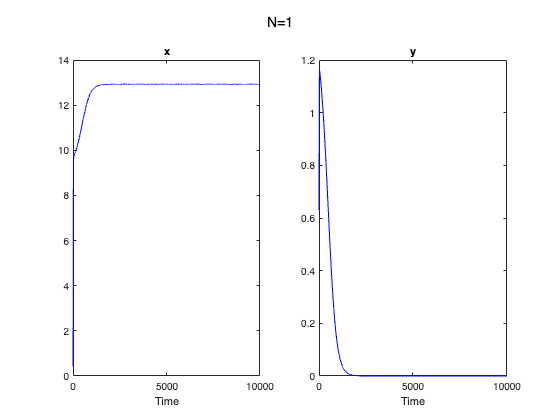



y = gsua_eval(T.Nominal,T);

y(:,end)

ans =    12.9292
    0.0000


## Análisis de incertidumbre

M=gsua_dmatrix(T,100);
Y=gsua_ua(M,T,'parallel',false);


**Matriz de diseño experimental**

T.clase=[0.4184 0.6315 0.2586 0.0203 0.0574 0.0097 0.0571 0.0048 0]'

T = 9×3 table
               Range          Nominal    clase 
          ________________    _______    ______

    x0    0.3347    0.5021     0.4184    0.4184
    y0    0.5052    0.7578     0.6315    0.6315
    a     0.2069    0.3103     0.2586    0.2586
    b     0.0162    0.0244     0.0203    0.0203
    c     0.0459    0.0689     0.0574    0.0574
    d     0.0078    0.0117    0.00975    0.0097
    m     0.0457    0.0685     0.0571    0.0571
    n     0.0038    0.0058     0.0048    0.0048
    u          0       0.1       0.05         0



nom=T.clase;
u_nominal=0.05;

Mdis=T.clase.*ones(1,101)+u_nominal*(-1:0.02:1).*[0 0 0 0 0 0 0 0 1]';
T.Properties.CustomProperties.Domain=[0 10000];

Mdis

Mdis =     0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184    0.4184
    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315    0.6315  

Sim101 Done
Sim100 Done
Sim99 Done
Sim98 Done
Sim97 Done
Sim96 Done
Sim95 Done
Sim94 Done
Sim93 Done
Sim92 Done
Sim91 Done
Sim90 Done
Sim89 Done
Sim88 Done
Sim87 Done
Sim86 Done
Sim85 Done
Sim84 Done
Sim83 Done
Sim82 Done
Sim81 Done
Sim80 Done
Sim79 Done
Sim78 Done
Sim77 Done
Sim76 Done
Sim75 Done
Sim74 Done
Sim73 Done
Sim72 Done
Sim71 Done
Sim70 Done
Sim69 Done
Sim68 Done
Sim67 Done
Sim66 Done
Sim65 Done
Sim64 Done
Sim63 Done
Sim62 Done
Sim61 Done
Sim60 Done
Sim59 Done
Sim58 Done
Sim57 Done
Sim56 Done
Sim55 Done
Sim54 Done
Sim53 Done
Sim52 Done
Sim51 Done
Sim50 Done
Sim49 Done
Sim48 Done
Sim47 Done
Sim46 Done
Sim45 Done
Sim44 Done
Sim43 Done
Sim42 Done
Sim41 Done
Sim40 Done
Sim39 Done
Sim38 Done
Sim37 Done
Sim36 Done
Sim35 Done
Sim34 Done
Sim33 Done
Sim32 Done
Sim31 Done
Sim30 Done
Sim29 Done
Sim28 Done
Sim27 Done
Sim26 Done
Sim25 Done
Sim24 Done
Sim23 Done
Sim22 Done
Sim21 Done
Sim20 Done
Sim19 Done
Sim18 Done
Sim17 Done
Sim16 Done
Sim15 Done
Sim14 Done
Sim13 Done
Sim12 Done
Sim11 Do

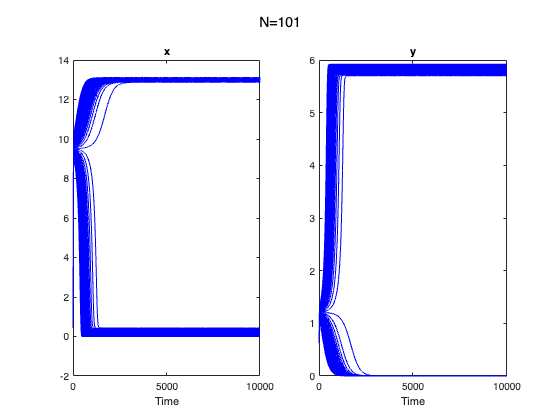


y=gsua_eval(Mdis,T,0:0.1:10000);


yss1=y(:,end,1)

yss1 =     0.0000
    0.0126
    0.0253
    0.0380
    0.0507
    0.0635
    0.0763
    0.0891
    0.1020
    0.1148


yss2=y(:,end,2)

yss2 =     5.9175
    5.9113
    5.9050
    5.8987
    5.8924
    5.8861
    5.8798
    5.8734
    5.8671
    5.8607


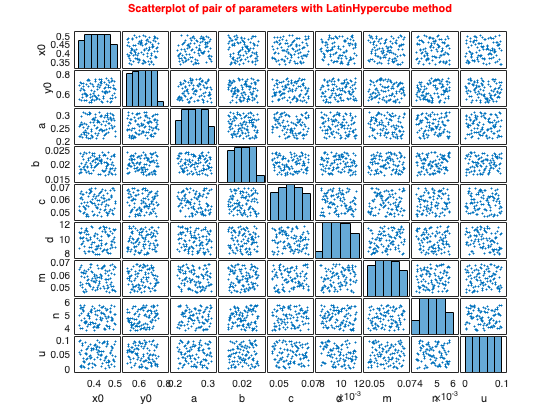


M=gsua_dmatrix(T,100,'Show','on');


ksf = u_nominal*(-1:0.02:1)

ksf =    -0.0500   -0.0490   -0.0480   -0.0470   -0.0460   -0.0450   -0.0440   -0.0430   -0.0420   -0.0410   -0.0400   -0.0390   -0.0380   -0.0370   -0.0360   -0.0350   -0.0340   -0.0330   -0.0320   -0.0310   -0.0300   -0.0290   -0.0280   -0.0270   -0.0260   -0.0250   -0.0240   -0.0230   -0.0220   -0.0210   -0.0200   -0.0190   -0.0180   -0.0170   -0.0160   -0.0150   -0.0140   -0.0130   -0.0120   -0.0110   -0.0100   -0.0090   -0.0080   -0.0070   -0.0060   -0.0050   -0.0040   -0.0030   -0.0020   -0.0010


ksf(1)

ans = -0.0500

**Curva de linealidad**

uin=u_nominal*(-1:0.02:1).*[0 0 0 0 0 0 0 0 1]';
figure(1)
clf
plot(uin,yss1)

Unrecognized function or variable 'yss1'.

hold on
plot(uin,yss2)
legend({'Población S. cerevisiae','Población S. Kephir'})
xlabel('U')
ylabel('Y_{ss}')
title("Curva de linealidad")

**Punto de equilibrio y su análisis de estabilidad para el sistema sin entradas**

syms x y a b c d n m
eq1 = x*(a-b*x-m*y);
eq2 = y*(c-d*y-n*x);
eqsinentrada = [eq1; eq2]

$$eqsinentrada = \left(\begin{array}{c} -x\,\left(b\,x-a+m\,y\right)\\ -y\,\left(d\,y-c+n\,x\right) \end{array}\right)$$

vars = [x y];
sol = solve(eqsinentrada == zeros(2,1),vars)

sol = struct with fields:
    x: [4×1 sym]
    y: [4×1 sym]


sol.x

$$ans = \left(\begin{array}{c} 0\\ \frac{a\,d-c\,m}{b\,d-m\,n}\\ \frac{a}{b}\\ 0 \end{array}\right)$$

sol.y

$$ans = \left(\begin{array}{c} 0\\ \frac{b\,c-a\,n}{b\,d-m\,n}\\ 0\\ \frac{c}{d} \end{array}\right)$$

solx = double(subs(sol.x,{'a' 'b','c','d','m','n'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048}))

solx =          0
    9.9666
   12.7389
         0


soly = double(subs(sol.y,{'a' 'b','c','d','m','n'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048}))

soly =          0
    0.9856
         0
    5.9175


ja=jacobian(eqsinentrada,vars)

$$ja = \left(\begin{array}{cc} a-2\,b\,x-m\,y & -m\,x\\ -n\,y & c-2\,d\,y-n\,x \end{array}\right)$$


x0 = solx(1);
y0 = soly(1);
ja1=double(subs(ja,{'a' 'b','c','d','m','n','x','y'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048,x0,y0}))

ja1 =     0.2586         0
         0    0.0574



x0 = solx(2);
y0 = soly(2);
ja4=double(subs(ja,{'a' 'b','c','d','m','n','x','y'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048,x0,y0}))

ja4 =    -0.2023   -0.5691
   -0.0047   -0.0096


x0 = solx(3);
y0 = soly(3);
ja3=double(subs(ja,{'a' 'b','c','d','m','n','x','y'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048,x0,y0}))

ja3 =    -0.2586   -0.7274
         0   -0.0037


x0 = solx(4);
y0 = soly(4);
ja2=double(subs(ja,{'a' 'b','c','d','m','n','x','y'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048,x0,y0}))

ja2 =    -0.0793         0
   -0.0284   -0.0574



[vec val] = eig(ja1);
val

val =     0.0574         0
         0    0.2586



[vec val] = eig(ja2);
val

val =    -0.0574         0
         0   -0.0793


[vec val] = eig(ja3);
val

val =    -0.2586         0
         0   -0.0037


[vec val] = eig(ja4);
val

val =    -0.2154         0
         0    0.0035


**Punto de equilibrio y su análisis de estabilidad para el sistema con entradas**

syms x y a b c d m n u
eq1 = x*(a-b*x-m*y)+u;
eq2 = y*(c-d*y-n*x);
eq = [eq1; eq2]

$$eq = \left(\begin{array}{c} u-x\,\left(b\,x-a+m\,y\right)\\ -y\,\left(d\,y-c+n\,x\right) \end{array}\right)$$


vars = [x y];
sol = solve(eq == zeros(2,1),vars)

sol = struct with fields:
    x: [4×1 sym]
    y: [4×1 sym]



sol.x

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{a-\sigma_{3}}{2\,b}\\ \frac{a+\sigma_{3}}{2\,b}\\ \frac{c+\frac{\sigma_{1}-2\,b\,c\,d+a\,d\,n+c\,m\,n}{\sigma_{2}}}{n}\\ \frac{c-\frac{\sigma_{1}+2\,b\,c\,d-a\,d\,n-c\,m\,n}{\sigma_{2}}}{n} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=n\,\sqrt{a^{2}\,d^{2}-2\,a\,c\,d\,m+c^{2}\,m^{2}+4\,b\,u\,d^{2}-4\,n\,u\,d\,m}\\ \sigma_{2}=2\,\left(b\,d-m\,n\right)\\ \sigma_{3}=\sqrt{a^{2}+4\,b\,u} \end{array}$$

sol.y

$$ans = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ -\frac{\sigma_{1}-2\,b\,c\,d+a\,d\,n+c\,m\,n}{2\,d\,\left(b\,d-m\,n\right)}\\ \frac{\sigma_{1}+2\,b\,c\,d-a\,d\,n-c\,m\,n}{2\,d\,\left(b\,d-m\,n\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=n\,\sqrt{a^{2}\,d^{2}-2\,a\,c\,d\,m+c^{2}\,m^{2}+4\,b\,u\,d^{2}-4\,n\,u\,d\,m} \end{array}$$

ja=jacobian(eq,vars)

$$ja = \left(\begin{array}{cc} a-2\,b\,x-m\,y & -m\,x\\ -n\,y & c-2\,d\,y-n\,x \end{array}\right)$$

solx = subs(sol.x,{'a' 'b','c','d','m','n'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048})

$$solx = \left(\begin{array}{c} \frac{1293}{203}-\frac{5000\,\sqrt{\frac{203\,u}{2500}+\frac{1671849}{25000000}}}{203}\\ \frac{5000\,\sqrt{\frac{203\,u}{2500}+\frac{1671849}{25000000}}}{203}+\frac{1293}{203}\\ \frac{38456}{7717}-\frac{50000000\,\sqrt{\frac{23107249}{39062500000000}-\frac{748549\,u}{250000000000}}}{7717}\\ \frac{50000000\,\sqrt{\frac{23107249}{39062500000000}-\frac{748549\,u}{250000000000}}}{7717}+\frac{38456}{7717} \end{array}\right)$$

soly = subs(sol.y,{'a' 'b','c','d','m','n'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048})

$$soly = \left(\begin{array}{c} 0\\ 0\\ \frac{2400000000\,\sqrt{\frac{23107249}{39062500000000}-\frac{748549\,u}{250000000000}}}{748549}+\frac{2583670}{748549}\\ \frac{2583670}{748549}-\frac{2400000000\,\sqrt{\frac{23107249}{39062500000000}-\frac{748549\,u}{250000000000}}}{748549} \end{array}\right)$$






uval = 0.05

uval = 0.0500

solx= double(subs(solx,{'a' 'b','c','d','m','n','u'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048 uval}))

solx =    -0.1905
   12.9294
    0.6765
    9.2901




soly = double(subs(soly,{'a' 'b','c','d','m','n','u'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048 uval}))

soly =          0
         0
    5.5828
    1.3204



s1 = [solx(3) soly(3)]

s1 =     0.6765    5.5828


sol1

Unrecognized function or variable 'sol1'.


T.clase=[0.4184 0.6315 0.2586 0.0203 0.0574 0.0097 0.0571 0.0048 uval]';
ynom=gsua_eval(T.clase,T,0:10000);

ynom(end,end,:)







uval = 0.05

uval = 0.0500

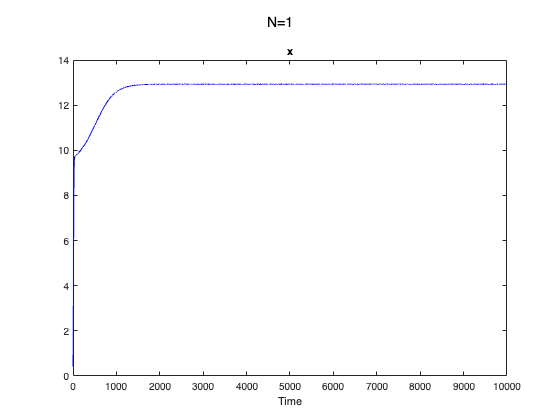

T.clase=[0.4184 0.6315 0.2586 0.0203 0.0574 0.0097 0.0571 0.0048 uval]';

ynom=gsua_eval(T.clase,T,0:10000);

ynom(end,end,:)

ans = 12.9289

uval = 0.2

uval = 0.2000

solx= double(subs(solx,{'a' 'b','c','d','m','n','u'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048 uval}))

solx =    -0.1905
   12.9294
    0.6765
    9.2901




soly = double(subs(soly,{'a' 'b','c','d','m','n','u'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048 uval}))

soly =          0
         0
    5.5828
    1.3204


s2 = [solx(2) soly(2)]

s2 =    12.9294         0


** Matrices del sistema lineal (solución 1)**


ja=jacobian(eq,vars)

$$ja = \left(\begin{array}{cc} a-2\,b\,x-m\,y & -m\,x\\ -n\,y & c-2\,d\,y-n\,x \end{array}\right)$$

uval = 0.02

uval = 0.0200

x0 = s1(1)

x0 = 0.6765

y0 = s1(2)

y0 = 5.5828


%solución 1
ja1=double(subs(ja,{'a' 'b','c','d','m','n','x','y'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048,x0,y0}))

ja1 =    -0.0876   -0.0386
   -0.0268   -0.0542



[vec val] = eig(ja1);
val1 = double(val(1,1))

val1 = -0.1072

val2 = double(val(2,2))

val2 = -0.0346

ja2=jacobian(eq,u)

$$ja2 = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$


A = ja1

A =    -0.0876   -0.0386
   -0.0268   -0.0542



B = double(ja2)

B =      1
     0


C = eye(2)

C =      1     0
     0     1


D = [0 ;0]

D =      0
     0


solu = solve(eq == 0,vars)

solu = struct with fields:
    x: [4×1 sym]
    y: [4×1 sym]


solu.x

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{a-\sigma_{3}}{2\,b}\\ \frac{a+\sigma_{3}}{2\,b}\\ \frac{c+\frac{\sigma_{1}-2\,b\,c\,d+a\,d\,n+c\,m\,n}{\sigma_{2}}}{n}\\ \frac{c-\frac{\sigma_{1}+2\,b\,c\,d-a\,d\,n-c\,m\,n}{\sigma_{2}}}{n} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=n\,\sqrt{a^{2}\,d^{2}-2\,a\,c\,d\,m+c^{2}\,m^{2}+4\,b\,u\,d^{2}-4\,n\,u\,d\,m}\\ \sigma_{2}=2\,\left(b\,d-m\,n\right)\\ \sigma_{3}=\sqrt{a^{2}+4\,b\,u} \end{array}$$

jaSol1 = subs(ja,{'x' 'y'},{solu.x(2),solu.y(2)})

$$jaSol1 = \left(\begin{array}{cc} -\sqrt{a^{2}+4\,b\,u} & -\frac{m\,\left(a+\sqrt{a^{2}+4\,b\,u}\right)}{2\,b}\\ 0 & c-\frac{n\,\left(a+\sqrt{a^{2}+4\,b\,u}\right)}{2\,b} \end{array}\right)$$

jaSol2 = subs(ja,{'x' 'y'},{solu.x(3),solu.y(3)})

$$jaSol2 = \begin{array}{l} \left(\begin{array}{cc} a-\frac{2\,b\,\left(c+\sigma_{1}\right)}{n}+\frac{m\,\sigma_{2}}{2\,d\,\left(b\,d-m\,n\right)} & -\frac{m\,\left(c+\sigma_{1}\right)}{n}\\ \frac{n\,\sigma_{2}}{2\,d\,\left(b\,d-m\,n\right)} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sigma_{2}}{2\,\left(b\,d-m\,n\right)}\\ \sigma_{2}=n\,\sqrt{a^{2}\,d^{2}-2\,a\,c\,d\,m+c^{2}\,m^{2}+4\,b\,u\,d^{2}-4\,n\,u\,d\,m}-2\,b\,c\,d+a\,d\,n+c\,m\,n \end{array}$$


jaSol10=subs(jaSol1,{'a' 'b','c','d','m','n'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048})

$$jaSol10 = \left(\begin{array}{cc} -\sqrt{\frac{203\,u}{2500}+\frac{1671849}{25000000}} & -\frac{571\,\sqrt{\frac{203\,u}{2500}+\frac{1671849}{25000000}}}{406}-\frac{738303}{2030000}\\ 0 & \frac{27229}{1015000}-\frac{24\,\sqrt{\frac{203\,u}{2500}+\frac{1671849}{25000000}}}{203} \end{array}\right)$$

jaSol20=subs(jaSol2,{'a' 'b','c','d','m','n'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048})

$$jaSol20 = \left(\begin{array}{cc} \frac{59870000\,\sqrt{\frac{23107249}{39062500000000}-\frac{748549\,u}{250000000000}}}{748549}-\frac{65875128}{467843125} & \frac{2855000\,\sqrt{\frac{23107249}{39062500000000}-\frac{748549\,u}{250000000000}}}{7717}-\frac{2744797}{9646250}\\ -\frac{11520000\,\sqrt{\frac{23107249}{39062500000000}-\frac{748549\,u}{250000000000}}}{748549}-\frac{1550202}{93568625} & -\frac{240000\,\sqrt{\frac{23107249}{39062500000000}-\frac{748549\,u}{250000000000}}}{7717}-\frac{258367}{7717000} \end{array}\right)$$


jaSolhelp = solve(eig(jaSol10)<=0,u,'ReturnConditions',true,'IgnoreAnalyticConstraints',true,'Real',true)

jaSolhelp = struct with fields:
             u: x
    parameters: x
    conditions: -1091461/5760000 <= x


bifurcation = -1091461/5760000

bifurcation = -0.1895

uvalor = jaSol10 == jaSol20

$$uvalor = \begin{array}{l} \left(\begin{array}{cc} -\sigma_{2}=\frac{59870000\,\sigma_{1}}{748549}-\frac{65875128}{467843125} & -\frac{571\,\sigma_{2}}{406}-\frac{738303}{2030000}=\frac{2855000\,\sigma_{1}}{7717}-\frac{2744797}{9646250}\\ 0=-\frac{11520000\,\sigma_{1}}{748549}-\frac{1550202}{93568625} & \frac{27229}{1015000}-\frac{24\,\sigma_{2}}{203}=-\frac{240000\,\sigma_{1}}{7717}-\frac{258367}{7717000} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{23107249}{39062500000000}-\frac{748549\,u}{250000000000}}\\ \sigma_{2}=\sqrt{\frac{203\,u}{2500}+\frac{1671849}{25000000}} \end{array}$$

solve(uvalor,u)

 
ans =
 
Empty sym: 0-by-1
 


jaSolhelp = solve(eig(jaSol20)<=0,u,'ReturnConditions',true,'IgnoreAnalyticConstraints',true,'Real',true)

jaSolhelp = struct with fields:
             u: [0×1 sym]
    parameters: [1×0 sym]
    conditions: [0×1 sym]




val1

val1 = -0.1072

val2

val2 = -0.0346

K = place(A,B,[-0.08, -0.05])

K =    -0.0118   -0.0346


xnew = 10

xnew = 10

ynew = 1

ynew = 1


%[A,B,C,D]=linmod('especies',s2,u_nominal)

** Matrices del sistema lineal (solución 2)**

uval = 0.02
x0 = s1(1)
y0 = s1(2)

%x0 = sol1(4)
%y0 = sol2(4)
ja1=double(subs(ja,{'a' 'b','c','d','m','n','x','y'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048 x0 y0}))
A = ja1
[vec val] = eig(ja1);
val1 = double(val(1,1))
val2 = double(val(2,2))

syms S Y(S) k r(S)
C = B'

C =      1     0


G = C*inv((eye(2)*S-A))*B

$$G = \frac{2251799813685248}{2251799813685248\,S+599731529838361}$$


[Pn,Pd]=numden(G)

$$Pn = 2251799813685248$$

$$Pd = 2251799813685248\,S+599731529838361$$

Pch=Pd+k*Pn

$$Pch = 2251799813685248\,S+2251799813685248\,k+599731529838361$$


kval = 1

kval = 1

val1 = -0.0935

val2 = -0.0452

K =     0.1664    0.4341


**Análisis de sensibilidad**

syms x(t) y(t) a b c d m n u
ode1=diff(x)==x*(a-b*x-m*y)+u;
ode2=diff(y)==y*(c-d*y-n*x);
odes=[ode1;ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=u-x\left(t\right)\,\left(b\,x\left(t\right)-a+m\,y\left(t\right)\right)\\ \frac{\partial }{\partial t}y\left(t\right)=-y\left(t\right)\,\left(d\,y\left(t\right)-c+n\,x\left(t\right)\right) \end{array}\right)$$

vars = [x y];
domain = [0 10000];
modelName = 'espcon';
gsua_dataprep(odes,vars,domain,modelName);

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccccccc} x\left(t\right) & y\left(t\right) & a & b & c & d & m & n & u \end{array}\right)$$

porc = 0.2;
x0nom = x0;
x0ran = [x0nom-x0nom*porc x0nom+x0nom*porc];
y0nom = y0;
y0ran = [y0nom-y0nom*porc y0nom+y0nom*porc];
anom = 0.2586;
aran = [anom-anom*porc anom+anom*porc];
bnom = 0.0203;
bran = [bnom-bnom*porc bnom+bnom*porc];
cnom = 0.0574;
cran = [cnom-cnom*porc cnom+cnom*porc];
dnom = 0.0097;
dran = [dnom-dnom*porc dnom+dnom*porc];
mnom = 0.0571;
mran = [mnom-mnom*porc mnom+mnom*porc];
nnom = 0.0048;
nran = [nnom-nnom*porc nnom+nnom*porc];
unom = 0.02;
uran = [unom-unom*porc unom+unom*porc];

Ranges = [x0ran; y0ran; aran; bran; cran; dran; mran; nran; 0 1];
[T,solver] = gsua_dataprep(odes,vars,domain,modelName,'range',Ranges)

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{ccccccccc} x\left(t\right) & y\left(t\right) & a & b & c & d & m & n & u \end{array}\right)$$

T = 9×2 table
                Range           Nominal
          __________________    _______

    x0     0.5412     0.8118    0.6765 
    y0     4.4662     6.6994    5.5828 
    a     0.20688    0.31032    0.2586 
    b     0.01624    0.02436    0.0203 
    c     0.04592    0.06888    0.0574 
    d     0.00776    0.01164    0.0097 
    m     0.04568    0.06852    0.0571 
    n     0.00384    0.00576    0.0048 
    u           0          1       0.5 


solver = function_handle with value:
    @(init,pars)ode45(@(t,Y)odefun(t,Y,pars),domain,[Table.Range(fixvars,1)',init],opt)




M = gsua_dmatrix(T,100);


T.Properties.CustomProperties.output = 1;


Tsa = gsua_sa(M,T, 'parallel', false)

Progress: 10%
Estimated processing time (h:m:s): 0:1:14
Remaining time (h:m:s): 0:1:7
Elapsed time (h:m:s): 0:0:6
Estimated stop time (h:m:s): 12:46:46
Number of simulations: 550
Progress: 19%
Estimated processing time (h:m:s): 0:1:11
Remaining time (h:m:s): 0:0:58
Elapsed time (h:m:s): 0:0:12
Estimated stop time (h:m:s): 12:46:43
Number of simulations: 550
Progress: 28%
Estimated processing time (h:m:s): 0:1:14
Remaining time (h:m:s): 0:0:54
Elapsed time (h:m:s): 0:0:20
Estimated stop time (h:m:s): 12:46:46
Number of simulations: 550
Progress: 37%
Estimated processing time (h:m:s): 0:1:15
Remaining time (h:m:s): 0:0:47
Elapsed time (h:m:s): 0:0:27
Estimated stop time (h:m:s): 12:46:47
Number of simulations: 550
Progress: 46%
Estimated processing time (h:m:s): 0:1:14
Remaining time (h:m:s): 0:0:40
Elapsed time (h:m:s): 0:0:33
Estimated stop time (h:m:s): 12:46:46
Number of simulations: 550
Progress: 55%
Estimated processing time (h:m:s): 0:1:13
Remaining time (h:m:s): 0:0:33
Elapsed ti

Tsa = 9×6 table
                Range           Nominal        Si            STi           STi_vec            Si_vec    
          __________________    _______    ___________    __________    ______________    ______________

    x0     0.5412     0.8118    0.6765     -1.4108e-06    0.00051114    1×10001 double    1×10001 double
    y0     4.4662     6.6994    5.5828      0.00024835      0.002198    1×10001 double    1×10001 double
    a     0.20688    0.31032    0.2586        0.081996       0.44852    1×10001 double    1×10001 double
    b     0.01624    0.02436    0.0203        0.052864       0.34666    1×10001 double    1×10001 double
    c     0.04592    0.06888    0.0574        0.022519       0.6

sum(Tsa.Si)/sum(abs(Tsa.Si))

ans = 1.0000


%Tiene que estar por encima de 0.65

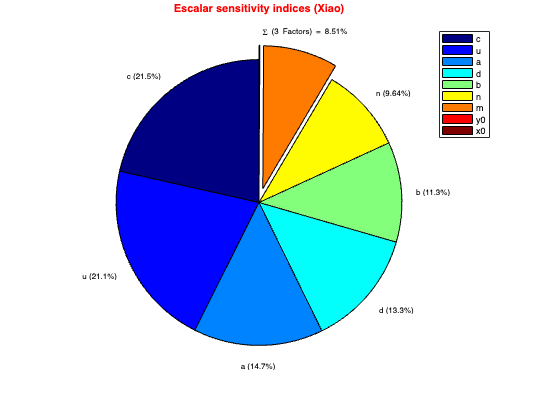

Operator '-' is not supported for operands of type 'string'.

Error in gsua_plot (line 218)
                    [c] = find( abs(t-tref(j)) <= min(abs(t-tref(j))) );


gsua_plot('Pie',Tsa,Tsa.STi)
gsua_plot('Pie',Tsa,Tsa.STi, colormap = 'jet')

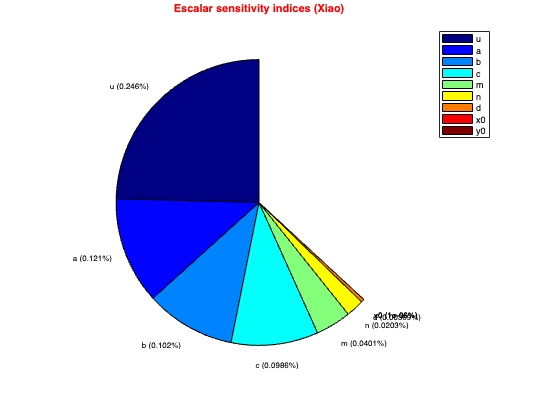

Operator '-' is not supported for operands of type 'string'.

Error in gsua_plot (line 218)
                    [c] = find( abs(t-tref(j)) <= min(abs(t-tref(j))) );

gsua_plot('Pie',Tsa,Tsa.Si)
gsua_plot('Pie',Tsa,Tsa.Si, colormap = 'jet')

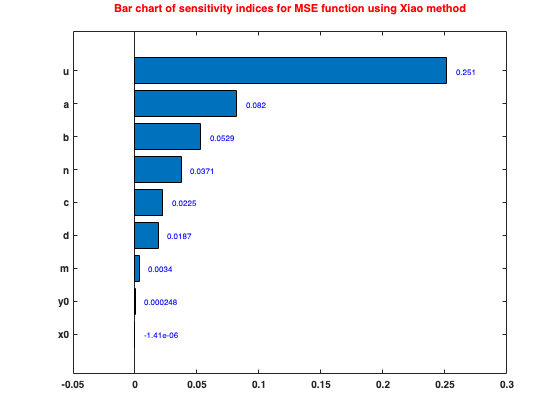

gsua_plot('Bar',Tsa,Tsa.Si)

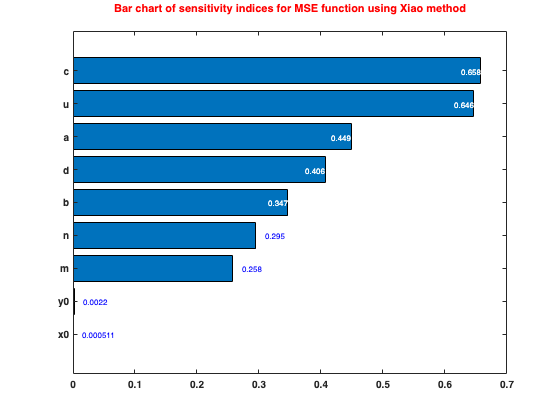

gsua_plot('Bar',Tsa,Tsa.STi)

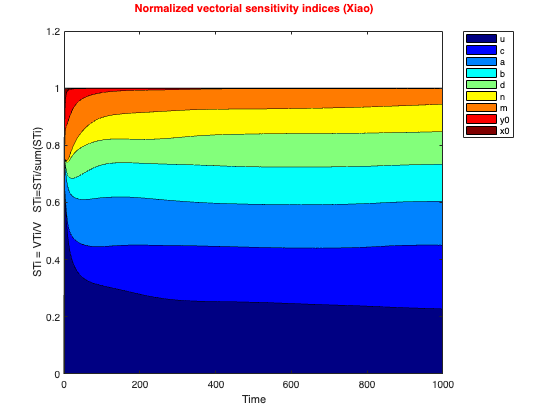

Give the right number of 4 function inputs
sens_plot('TotalSensitivityArea',Par,ST,t)


xdata= 0:1000;

gsua_plot('TotalSensitivityArea',Tsa,Tsa.STi_vec,xdata)
gsua_plot('TotalSensitivityArea',Tsa,Tsa.STi_vec,xdata, colormap = 'jet')

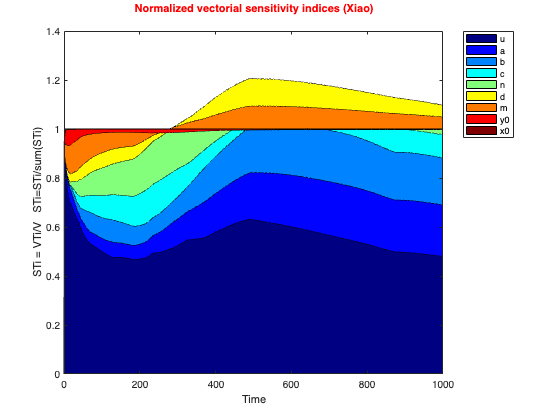

Give the right number of 4 function inputs
sens_plot('TotalSensitivityArea',Par,ST,t)


clf

gsua_plot('TotalSensitivityArea',Tsa,Tsa.Si_vec,xdata)
gsua_plot('TotalSensitivityArea',Tsa,Tsa.Si_vec,xdata, colormap = 'jet')

## Preparación del modelo en simulink

x0 = 0.6765;
y0 = 5.5828;
A = [-0.0876 -0.0386; -0.0268 -0.0542];
B = [1;0];
Aa=double(subs(A,{'a' 'b','c','d','m','n','x','y'},{0.2586 0.0203 0.0574 0.0097 0.0571 0.0048 x0 y0}))

Aa =    -0.0876   -0.0386
   -0.0268   -0.0542



[vec val] = eig(Aa);
double(val(1,1))

ans = -0.1071

double(val(2,2))

ans = -0.0347

K = place(A,B,[-0.08, -0.05])

K =    -0.0118   -0.0346


porc = 0.2;
x0nom = x0;
x0ran = [x0nom-x0nom*porc x0nom+x0nom*porc];
y0nom = y0;
y0ran = [y0nom-y0nom*porc y0nom+y0nom*porc];
anom = 0.2586;
aran = [anom-anom*porc anom+anom*porc];
bnom = 0.0203;
bran = [bnom-bnom*porc bnom+bnom*porc];
cnom = 0.0574;
cran = [cnom-cnom*porc cnom+cnom*porc];
dnom = 0.0097;
dran = [dnom-dnom*porc dnom+dnom*porc];
mnom = 0.0571;
mran = [mnom-mnom*porc mnom+mnom*porc];
nnom = 0.0048;
nran = [nnom-nnom*porc nnom+nnom*porc];
unom = 0.02;
uran = [unom-unom*porc unom+unom*porc];

model='especiesMIMO';
ParIn={'x0','y0','a','b','c','d','m','n'};
Ranges = [x0ran; y0ran; aran; bran; cran; dran; mran; nran];
out_names = {'x','y'};
T = gsua_dataprep(model,Ranges,ParIn,'out_names',out_names)

Setting environment to work with simulink
Setting nominal values
All done!


T = 8×2 table
                Range           Nominal
          __________________    _______

    x0     0.5412     0.8118    0.6765 
    y0     4.4662     6.6994    5.5828 
    a     0.20688    0.31032    0.2586 
    b     0.01624    0.02436    0.0203 
    c     0.04592    0.06888    0.0574 
    d     0.00776    0.01164    0.0097 
    m     0.04568    0.06852    0.0571 
    n     0.00384    0.00576    0.0048 


M = gsua_dmatrix(T,100);


Generating xdata and ynom values
Progress: 100%
Estimated processing time (h:m:s): 0:0:51
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:51
Estimated stop time (h:m:s): 10:31:38
Number of simulations: 100


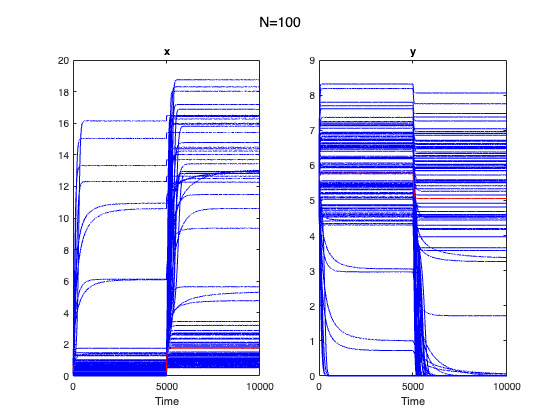

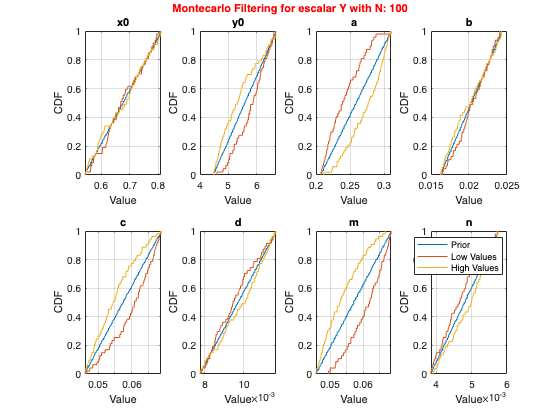

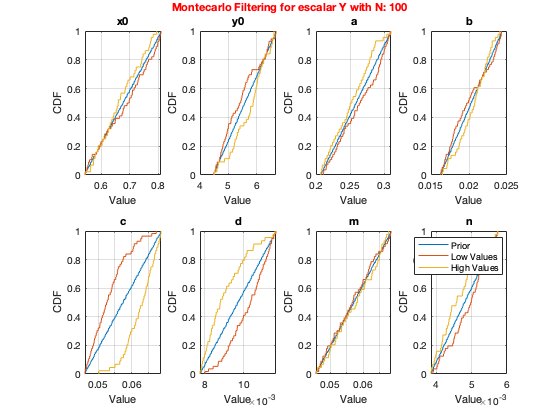

Y = Y(:,:,1) =

  Columns 1 through 999

    0.7154    0.6831    0.6508    0.6185    0.5880    0.5675    0.5469    0.5264    0.5059    0.4853    0.4648    0.4443    0.4237    0.4032    0.3826    0.3621    0.3416    0.3210    0.3005    0.2853    0.2716    0.2578    0.2441    0.2304    0.2167    0.2029    0.1892    0.1755    0.1617    0.1480    0.1343    0.1216    0.1116    0.1016    0.0916    0.0816    0.0715    0.0615    0.0515    0.0415    0.0315    0.0215    0.0115    0.0015         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

T.Properties.CustomProperties.output = 1:2;
Y = gsua_ua(M,T,'parallel',false)

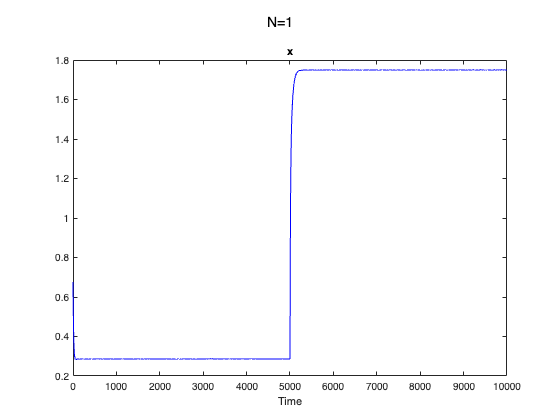

T.Properties.CustomProperties.output = 1;
ynom = gsua_eval(T.Nominal,T);


Tsa1 = gsua_sa(M,T,'parallel', false,'SensMethod','Saltelli','ynom',ynom)

Progress: 10%
Estimated processing time (h:m:s): 0:4:25
Remaining time (h:m:s): 0:3:59
Elapsed time (h:m:s): 0:0:26
Estimated stop time (h:m:s): 10:43:1
Number of simulations: 500
Progress: 20%
Estimated processing time (h:m:s): 0:4:34
Remaining time (h:m:s): 0:3:39
Elapsed time (h:m:s): 0:0:54
Estimated stop time (h:m:s): 10:43:10
Number of simulations: 500
Progress: 30%
Estimated processing time (h:m:s): 0:4:13
Remaining time (h:m:s): 0:2:57
Elapsed time (h:m:s): 0:1:16
Estimated stop time (h:m:s): 10:42:49
Number of simulations: 500
Progress: 40%
Estimated processing time (h:m:s): 0:3:51
Remaining time (h:m:s): 0:2:18
Elapsed time (h:m:s): 0:1:32
Estimated stop time (h:m:s): 10:42:27
Number of simulations: 500
Progress: 50%
Estimated processing time (h:m:s): 0:4:5
Remaining time (h:m:s): 0:2:2
Elapsed time (h:m:s): 0:2:2
Estimated stop time (h:m:s): 10:42:41
Number of simulations: 500
Progress: 60%
Estimated processing time (h:m:s): 0:4:6
Remaining time (h:m:s): 0:1:38
Elapsed time 

Tsa1 = 8×6 table
                Range           Nominal        Si           STi           STi_vec            Si_vec    
          __________________    _______    __________    __________    ______________    ______________

    x0     0.5412     0.8118    0.6765     0.00061916    1.4484e-05    1×10001 double    1×10001 double
    y0     4.4662     6.6994    5.5828        0.16418       0.18789    1×10001 double    1×10001 double
    a     0.20688    0.31032    0.2586        0.11493       0.51484    1×10001 double    1×10001 double
    b     0.01624    0.02436    0.0203       0.017665       0.44051    1×10001 double    1×10001 double
    c     0.04592    0.06888    0.0574      -0.034694       0.56885  

sum(Tsa1.Si)/sum(abs(Tsa1.Si))

ans = 0.8487

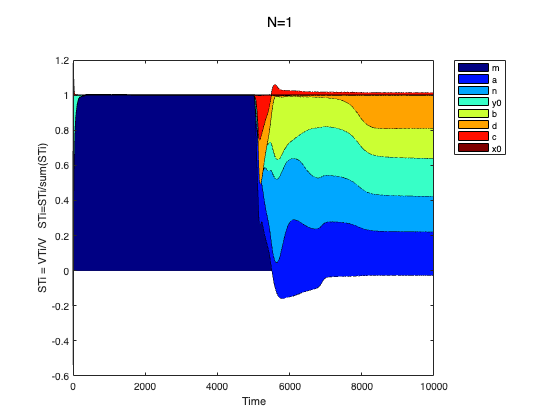

Give the right number of 4 function inputs
sens_plot('TotalSensitivityArea',Par,ST,t)


xdata= 0:10000;
gsua_plot('TotalSensitivityArea',Tsa1,Tsa1.Si_vec,xdata)
gsua_plot('TotalSensitivityArea',Tsa1,Tsa1.Si_vec,xdata, colormap = 'jet')